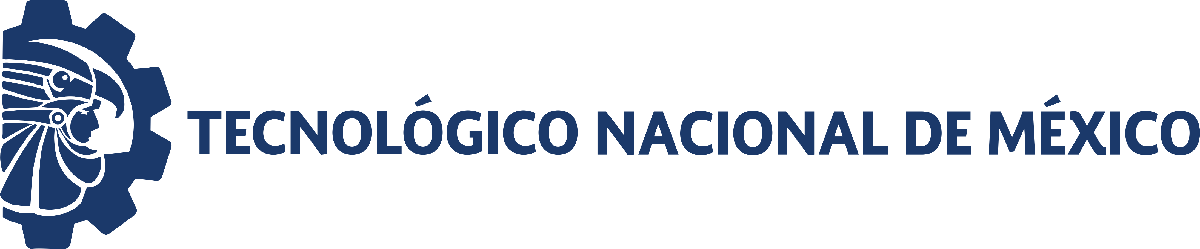                                 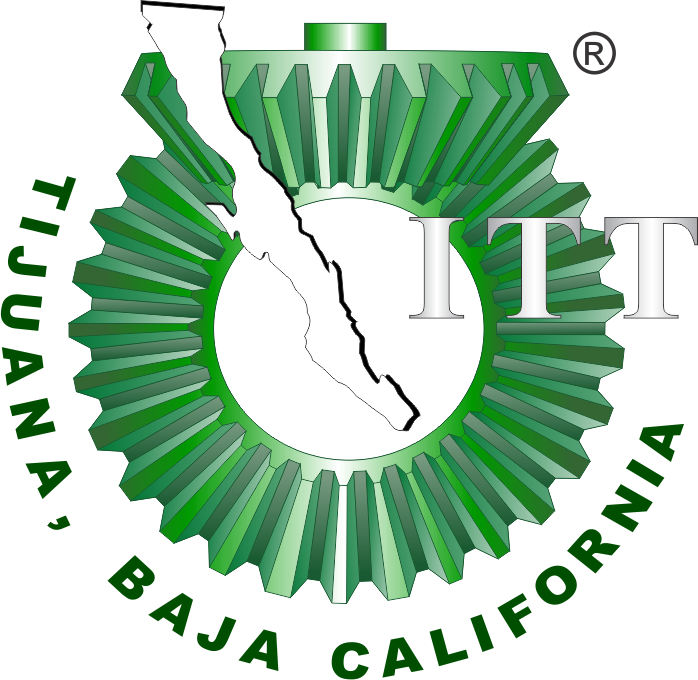

# Práctica trew: Sistema Musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

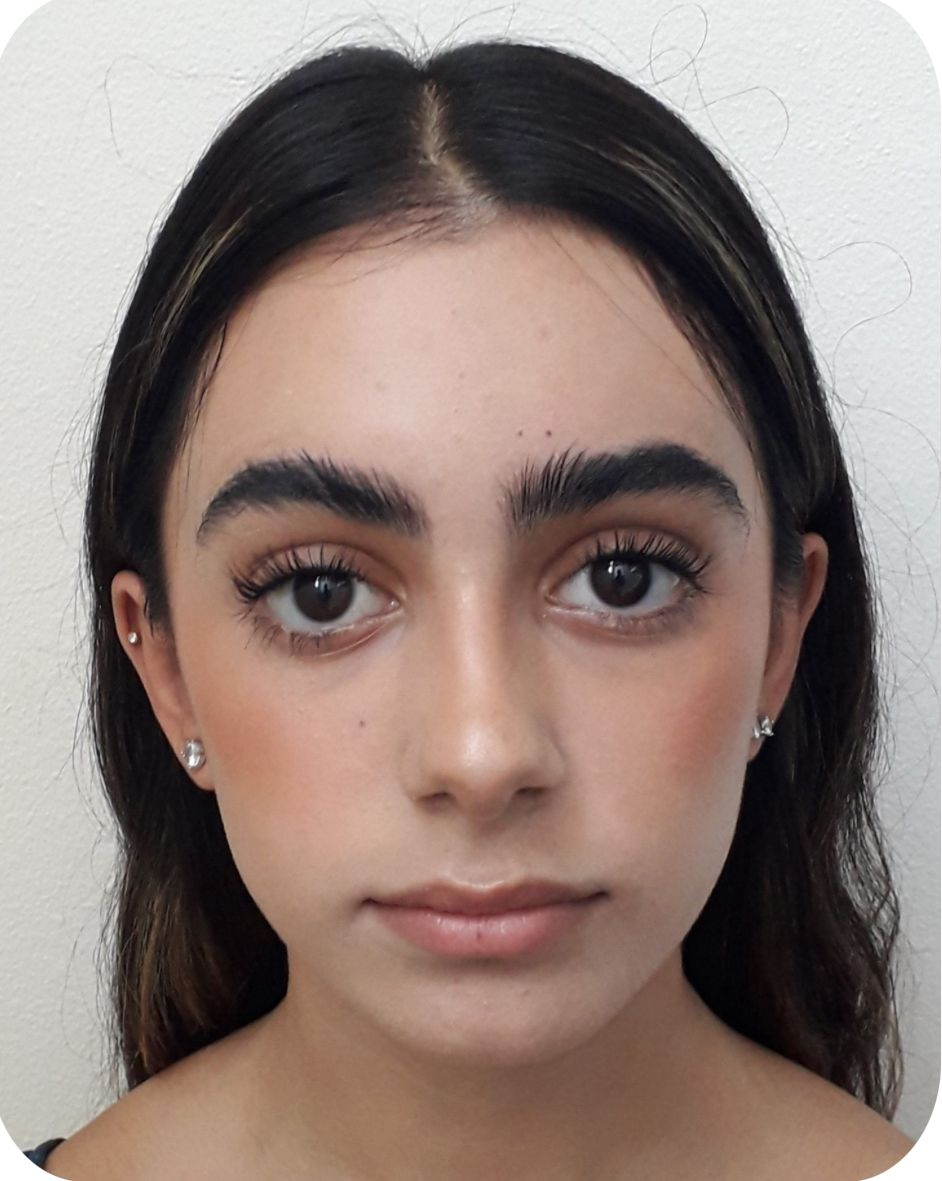

Nombre del alumno: Ximena Solis Marrufo

Número de control: 22212274

Correo institucional: L22212274**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all');
tend = '10';
file = 'practica3';
open_system(file);
parameters.StopTime=tend;
parameters.Solver = "ode15s";
parameters.MaxStep = '1E-3';
set_param('practica3/F(t)','PulseType','Time Based');
set_param('practica3/F(t)','TimeSource','Use simulation time');
set_param('practica3/F(t)','Amplitude','1');
set_param('practica3/F(t)','Period','10');
set_param('practica3/F(t)','PulseWidth','10');
set_param('practica3/F(t)','PhaseDelay','1');

## Respuesta en lazo abierto

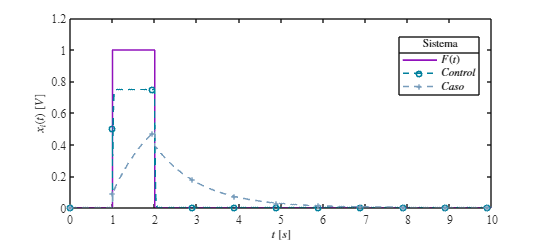

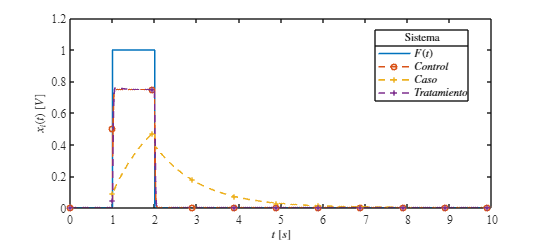

x=sim(file,parameters);
plotsignals(x.t,x.F,x.Fs1,x.Fs2,x.Fs3);

## Funcion : Respuesta a las señales

function plotsignals(t,F,Fs1,Fs2,Fs3)
    set(figure(), 'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    
    mycolors=[145,18,188;
        0,128,157;
        120,157,188;
        203,4,4;
        125,150,117;
        0,0,1]/255;

    colororder(mycolors)
   p=(plot(t,F,'-',t,Fs1,'--o',t,Fs2,'--+',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t)));
    L= legend('$F(t)$','$Control$','$Caso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','Best','Box','On');
    title(L,'Sistema', 'FontSize',10)
 
    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)
    xlim([0,10]); xticks(0:1:10);
    ylim([0,1.2]); yticks(0:.2:1.4);

    exportgraphics(gcf,['GraficaLa.pdf'],'ContentType','vector');
    exportgraphics(gcf,['GraficaLa.png'],'ContentType','vector');
    
    set(figure(), 'Color', 'w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;

    p=(plot(t,F,'-',t,Fs1,'--o',t,Fs2,'--+',t,Fs3,'--+',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t)));
    L= legend('$F(t)$','$Control$','$Caso$','$Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','Best','Box','On');
    title(L,'Sistema', 'FontSize',10)
 
    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$x_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)
    xlim([0,10]); xticks(0:1:10);
    ylim([0,1.2]); yticks(0:.2:1.4);
   
    exportgraphics(gcf,['GraficaLc.pdf'],'ContentType','vector');
    exportgraphics(gcf,['GraficaLc.png'],'ContentType','vector');

 
end
